# Getting Started with VERDICT

## Description

Fitting of VERDICT model

## System Requirements

MATLAB Statistics and Machine Learning Toolbox (for probability distribution of radii)

## Features

Fits AMICO-style tissue model to data. Currently uses `lsqnonneg` to fit unknown volume fractions for 3 types of compartment: spheres with a range of radii, astrosticks and "ball". 

## Examples

See test suite in folder `test`.

The code below provides an example of running `verdict_simulate`, adding noise and then calling `verdict_fit`. Within `verdict_simulate`, a normal distribution of radii is created. 

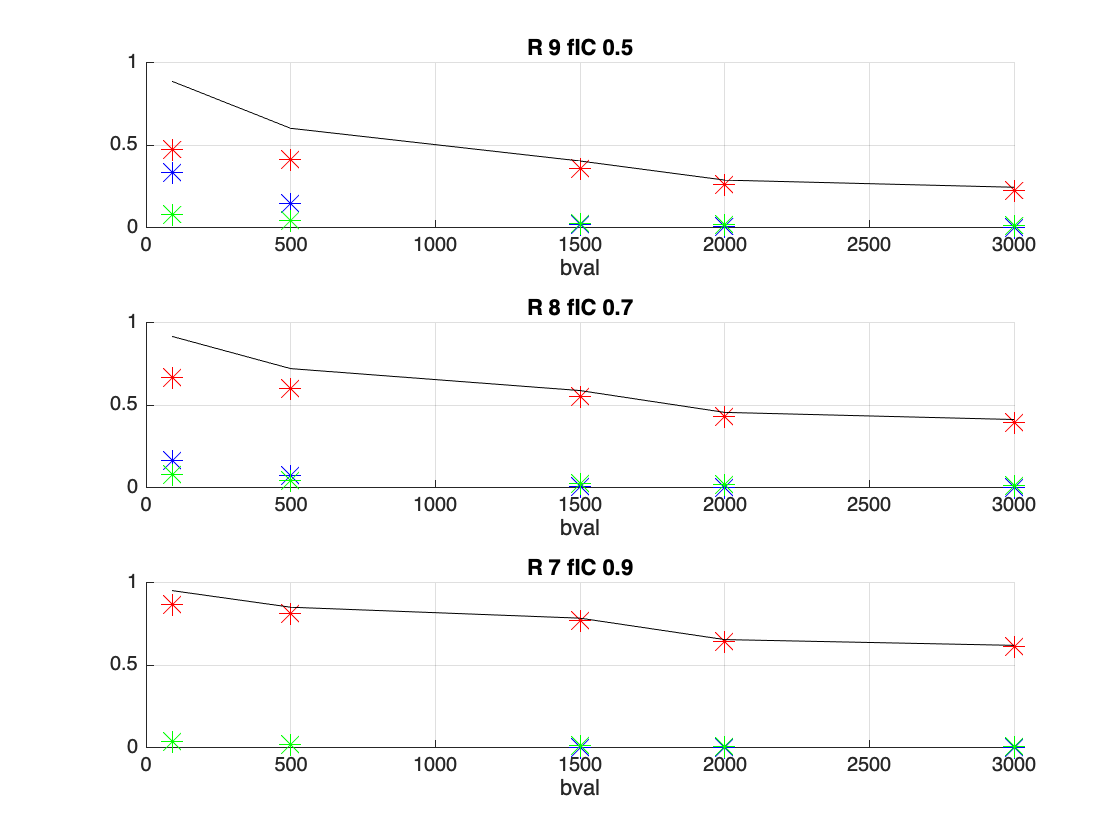

[gndt, scheme, Y, t, opt] = verdict_simulate ; % simulates data for 3 voxels

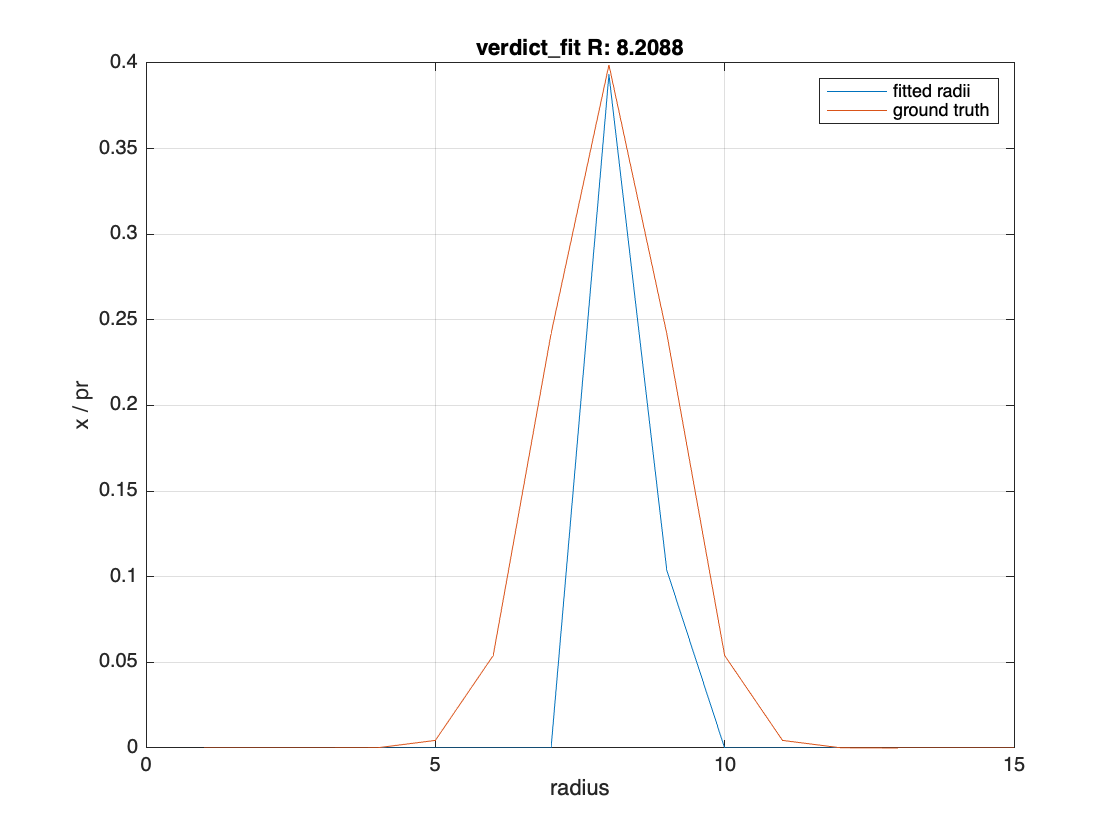

Ynoise = abs(addnoise(Y,'snr',20,'signal',1) ); % add noise

tCell = namedargs2cell(t) ; optCell = namedargs2cell(opt) ;
[fIC, fEES, fVASC, R, A] = verdict_fit(scheme, Ynoise, tCell{:}, optCell{:}) ; % do fitting

% pick one of the three voxels
ivox = 2 ;
y1 = Ynoise(ivox,1,1,:) ;

% lsqnonneg is used in verdict_fit
x = lsqnonneg(A,y1(:)) ;

figure
nr = length(t.Rs) ;

plot(t.Rs,x(1:nr), 'DisplayName','fitted radii')
hold on
plot(t.Rs,gndt.rDist{ivox}, 'DisplayName','ground truth')
xlabel('radius')
ylabel('x / pr')
title(['verdict_fit R: ',num2str(R(ivox))],'Interpreter','none')
legend
grid on

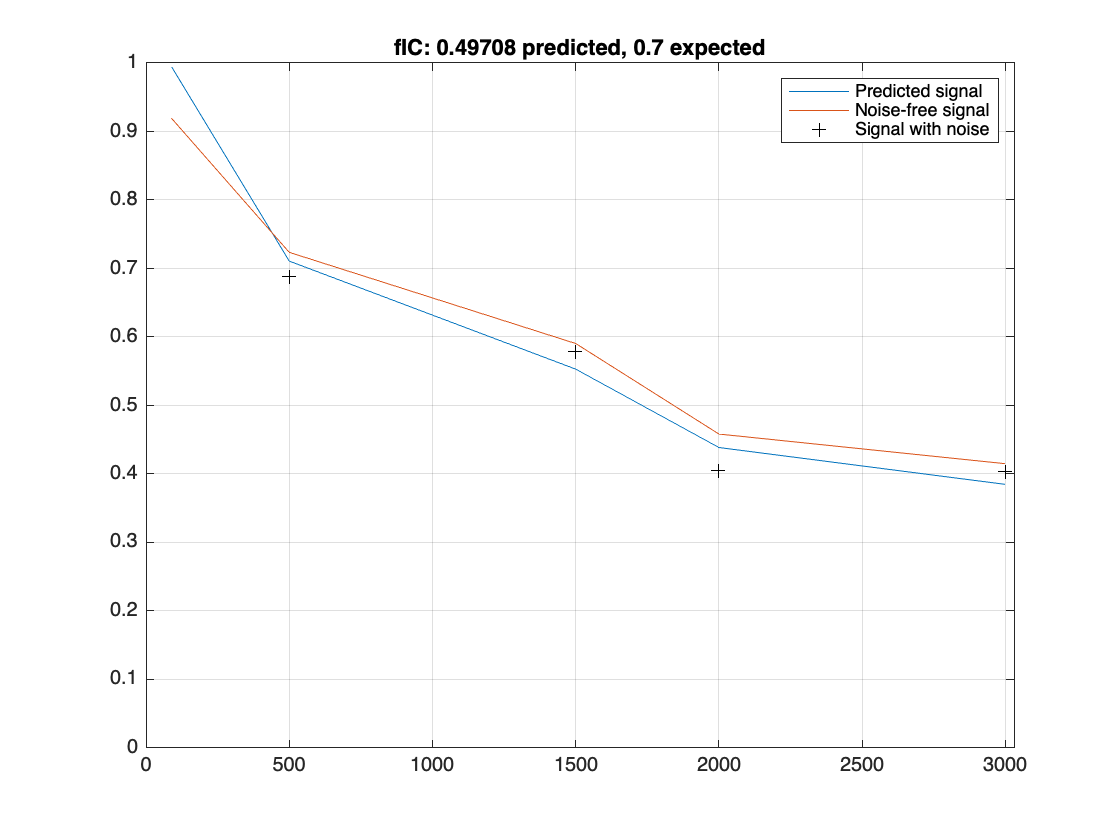

% compare predicted signal and original
figure
ypred = A * x ;
plot([scheme(:).bval]',ypred ,'DisplayName','Predicted signal')
hold on, grid on
ynfree = Y(ivox,1,1,:) ;
plot([scheme(:).bval]',ynfree(:),'DisplayName','Noise-free signal')
plot([scheme(:).bval]',y1(:),'k+' ,'DisplayName','Signal with noise')
axis([0 3030 0 1])
legend
title(['fIC: ',num2str(fIC(ivox)),' predicted, ',num2str(gndt.fIC(ivox)),' expected'])